# SCRIPT COLLECTION

## ext2int (renumber buses succinctively)

c = 'case300';
mpc = loadcase(strcat(c,'.m'));
mpci = ext2int(mpc);
savecase(strcat(c,'.m'), mpci);

## extract PTDF

c = 'case5';
mpc = loadcase(strcat(c,'.m'));
ptdf = makePTDF(mpc);
save(strcat(c,'_PTDF.mat'), 'ptdf');

## convert .mat to .m

% c = 'results_caseTurkish_dataset_mpc'
c = 'case5_artificial'

c = 'case5_artificial'

mpc = loadcase(strcat(c, '.mat'));
savecase(strcat(c, '.m'), mpc, mpc.version);

## convert .m to .mat

% c = 'results_caseTurkish_dataset_mpc'
c = 'case5'

c = 'case5'

mpc = loadcase(strcat(c, '.m'));
savecase(strcat(c, '.mat'), mpc, mpc.version);

## plot network

c = 'case118' % case39

c = 'case118'


MATPOWER Version 7.1, 08-Oct-2020 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.22 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses            118     Total Gen Capacity    9966.2       -7345.0 to 11777.0
Generators        54     On-line Capacity      9966.2       -7345.0 to 11777.0
Committed Gens    54     Generation (actual)   4374.9             795.7
Loads             99     Load                  4242.0            1438.0
  Fixed           99       Fixed               4242.0            1438.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0 

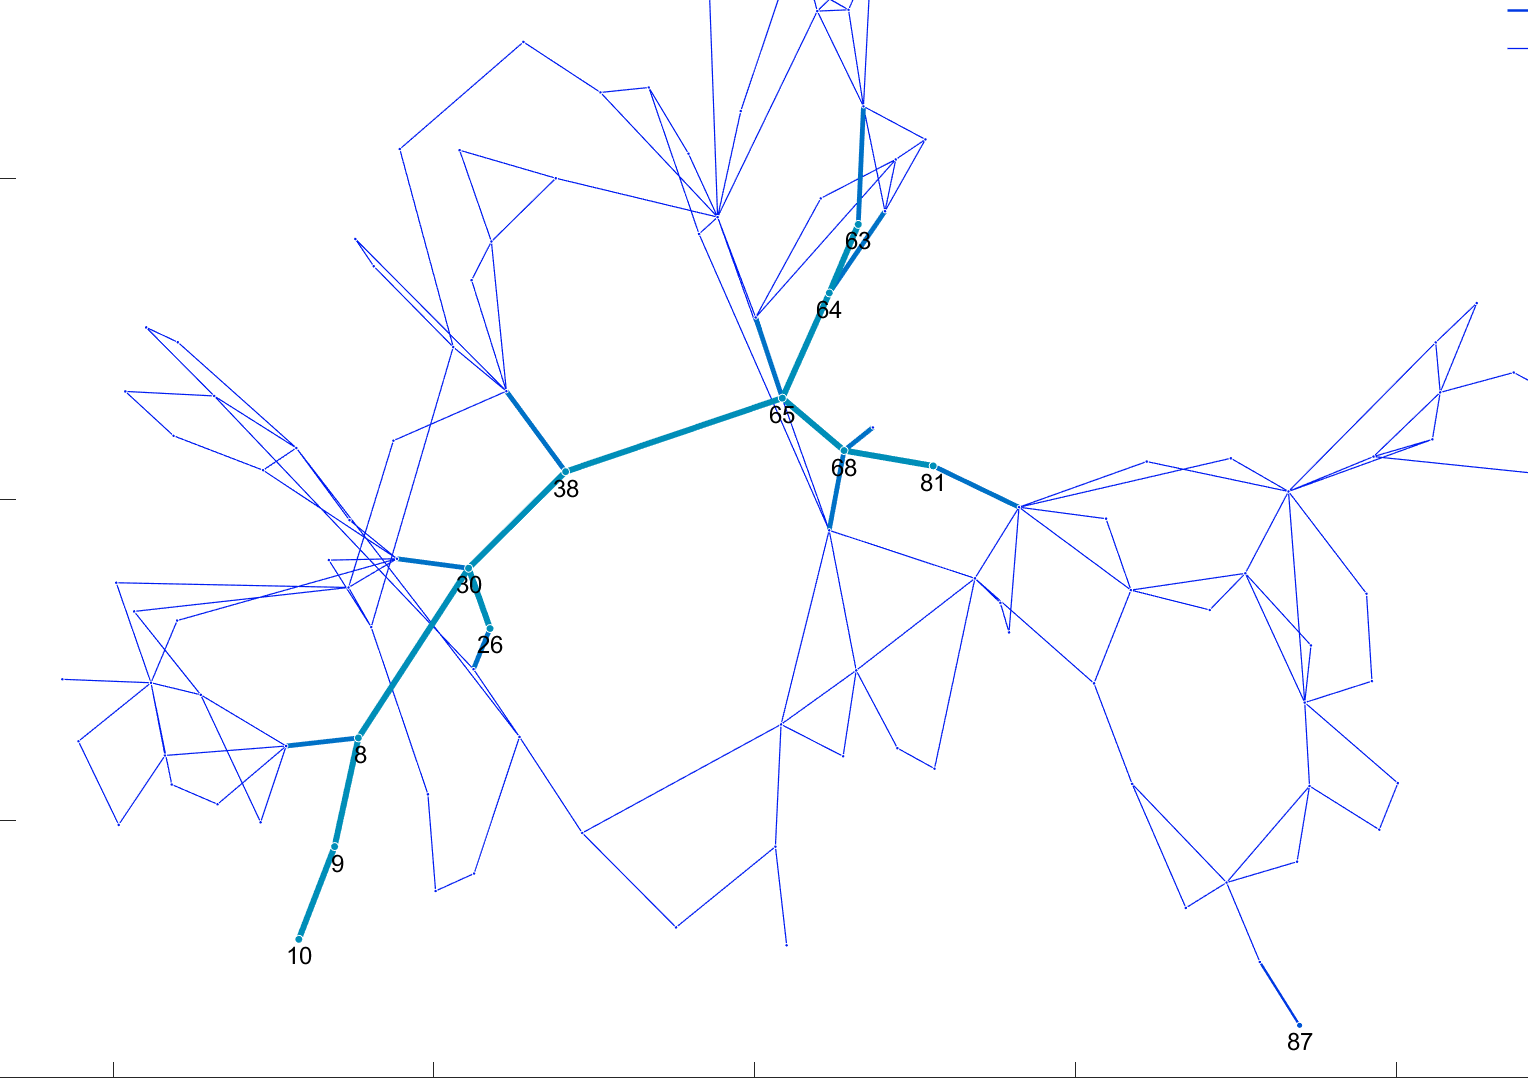

mpc = loadcase(strcat(c, '.m'));
plot_mpc(mpc, 'MaxBusLabels', 40, 'FigSize', 5);

## add c0 cost coeff.

% deletes one colum!
c = 'case5'

c = 'case5'

mpc = loadcase(strcat(c, '_OLD.m'));
mpc.gencost(:,7) = mpc.gencost(:,6);
mpc.gencost(:,6) = mpc.gencost(:,5);
mpc.gencost(:,5) = 0.01;
savecase(strcat(c,'.m'), mpc);


## agglomerate multiple generators and their costs

c = 'case5'

c = 'case5'

mpc = loadcase(strcat(c, '_OLD.m'));

mpc = struct with fields:
    version: '2'
    baseMVA: 100
        bus: [5×13 double]
        gen: [5×21 double]
     branch: [6×13 double]
    gencost: [5×7 double]



buses = mpc.gen(:,1)

buses =      1
     1
     3
     4
     5


gen_buses = unique(buses);
l = length(gen_buses);
n = length(mpc.gen(1,:));
nc = length(mpc.gencost(1,:))

nc = 7


% new arrays
new_gen = zeros(l, size(mpc.gen,2));
new_gen(:,1) = gen_buses;
new_gencost = zeros(l,size(mpc.gencost,2));

% agglomerate generators
for i=1:length(mpc.gen(:,1))
    % e.g.: gen_buses=[1,2,4,...] - gen_bus=4 is the idx=3rd bus that has a generator
    gen_bus = mpc.gen(i,1);
    idx = find(new_gen(:,1)==gen_bus); 
    
    % agglomerate generators
    gen_row = mpc.gen(i,2:n);
    new_gen(idx,2:5) = new_gen(idx,2:5) + gen_row(1:4); % sum of P, Q, Qmin, Qmax
    new_gen(idx,6:8) = gen_row(5:7); % constant values
    new_gen(idx,9:10) = new_gen(idx,9:10) + gen_row(8:9); % sum of Pmax, Pmin
    new_gen(idx,11:n) = gen_row(10:n-1); % constant values
    
    % agglomerate generator costs
    gencost_row = mpc.gencost(i,:);
    new_gencost(idx,1:4) = gencost_row(1:4); % constant values
    new_gencost(idx,5:nc) = new_gencost(idx,5:nc) + gencost_row(5:nc); % sum of cost coefficients
end

ans = 21

ans = 21

ans = 21

ans = 21

ans = 21


mpc.gen = new_gen;
mpc.gencost = new_gencost;

savecase(strcat(c, '.m'),mpc);

## case57: add rateA

c = 'case118' 

c = 'case118'

mpc = loadcase(strcat(c, '.m'));
mpc.branch(:,6) = mpc.branch(:,6) + 600;
savecase(strcat(c, '.m'), mpc);

## case300: add rateA

mpc = loadcase('case300.m')

mpc = struct with fields:
    version: '2'
    baseMVA: 100
        bus: [300×13 double]
        gen: [69×21 double]
     branch: [411×13 double]
    gencost: [69×7 double]


% set rateA to a default of 600
nr_branches = length(mpc.branch)

nr_branches = 411

rateA = 800 * ones(nr_branches,1)

rateA =    800
   800
   800
   800
   800
   800
   800
   800
   800
   800


mpc.branch(:,6) = rateA

mpc = struct with fields:
    version: '2'
    baseMVA: 100
        bus: [300×13 double]
        gen: [69×21 double]
     branch: [411×13 double]
    gencost: [69×7 double]


savecase('case300.m', mpc.baseMVA, mpc.bus, mpc.gen, mpc.branch, mpc.gencost)

## caseTurkish: total gen/load

mpc = loadcase('case300.m');
sum(mpc.bus(:,3)) % total demand (Pd)

ans = 2.3276e+04

sum(mpc.gen(:,2)) % total generation (Pg)

ans = 2.3479e+04

## Debug OPF

% c = 'case300';
% c = 'caseGB';
% c = 'case39';
% c = 'caseTurkish';
% c = 'case39_v01';
c = 'case57';


clear mpcbase
clear mpctarget
% 
% define_constants;
mpcbase = loadcase(strcat(c,'.m'));
mpctarget = loadcase(strcat(c,'.m'));

%mpcbase.bus(:, BUS_TYPE) = 2; % all buses at PV (=2) instead of PQ (=1)
%mpctarget.bus(:, BUS_TYPE) = 2;

% important
% mpcbase.bus(:, QD) = 0;
% mpctarget.bus(:, QD) = mpcbase.bus(:, QD);

% important
% mpcbase.bus(:, PD) = 100; % zero real power demand
% mpctarget.bus(:, PD) = 2 * mpcbase.bus(:, PD);

% % important
% mpcbase.gen(:, PG) = 100;
% mpctarget.gen(:, PG) = 2 * mpcbase.gen(:, PG);

% mpcbase.gen(:, QG) = 0;
% mpctarget.gen(:, QG) = mpcbase.gen(:, QG);

% mpcbase.gen(:, PMAX) = 2.5 * mpcbase.gen(:, PG);
% mpcbase.branch(:, BR_R) = 0.0001; % zero resistance (lines & transformers)
% mpcbase.branch(:, BR_X) = 0.001; % zero reactance

% res = runcpf(mpcbase, mpctarget); 
% res.cpf.max_lam
% res.success

% res = rundcpf(strcat(c,'.m'));
% res

% res = runopf(strcat(c,'.m'));
% res

mpopt = mpoption()
res = rundcopf(strcat(c,'.m'),mpopt,strcat(c,'_print.m'), strcat('results_',c,'_mpc.m'));
% res = rundcopf(mpcbase)
% res = rundcopf(strcat(c,'.m'))
res.success

mpc = loadcase(strcat('results_',c,'_mpc.m'));
savecase(strcat('results_',c,'_mpc.mat'), mpc, mpc.version);

% save(strcat('results_',c,'.m'), 'res')

## RunOPF

% c = 'caseTurkish_paper'
% c = 'case39'
c = 'case300'
runopf_(c)

Function:

function runopf_(name)
    mpopt = mpoption();
    res = rundcopf(strcat(name,'.m'),mpopt,strcat('results_',name,'_print.m'), strcat('results_',name,'_mpc.m'));
    % res = rundcopf(mpcbase)
    % res = rundcopf('caseTurkish_dataset.m')
    res.success
    
    mpc = loadcase(strcat('results_',name,'_mpc.m'));
    savecase(strcat('results_',name,'_mpc.mat'), mpc, mpc.version);
end